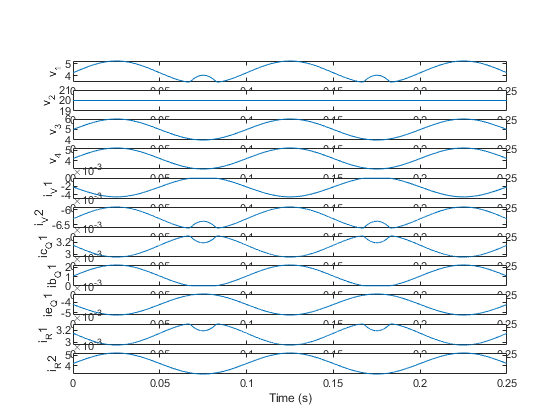

close all;
clear;
clc;

%File is a tab-delimited table of simulation results
%Row 1 contains headers
%Column 1 contains time values

%Generate an example in LTspice by running a simulation
% and choosing File -> Export data as text

%Navigate to folder that contains the csv/txt files
cd ../Desktop/

%Input files can be either csv or txt files

%LTS_V2 input file name
datafile = "out.csv";

%LTspice input file name (optional => replace with "" when no file)
datafile1 = "";

%Plot specific data on an extra graph to see more detail
specificHeader = "v_1"; %Header of LTS_V2 data
specificHeader1 = "V(n001)"; %Header of LTspice data

graphTitle = "v_1"; %if graphTitle="", the column header name will be used
headerAxisName = "Voltage (V)";



%Get LTS_V2 simulation data
if endsWith(datafile,".csv")
    simfile = importdata(datafile, ",", 1);
else
    simfile = importdata(datafile,'\t',1);
end
simdata = simfile.data;

%Get LTspice simulation data
if datafile1 == ""
    %do nothing
elseif endsWith(datafile1,".csv")
    simfile1 = importdata(datafile1, ",", 1);
    simdata1 = simfile1.data;
else
    simfile1 = importdata(datafile1,'\t',1);
    simdata1 = simfile1.data;
end

%Loop over columns of LTS_V2 data and plot everything on same graph
figure;
for n = 2:(size(simdata,2))
    subplot(size(simdata,2),1,n);   %Add a set of axes
    plot(simdata(:,1),simdata(:,n)); %Add the data
    ylabel(simfile.colheaders(n));  %Label the Y axis with the column header
end
xlabel('Time (s)'); %Label the x axis of the bottom plot





figure;
%Plot LTS_V2 data
for n = 2:(size(simdata, 2))
    if simfile.colheaders(n) == specificHeader
         plot(simdata(:,1),simdata(:,n),'LineWidth',2); %Add the data
         
         if graphTitle == ""
             title(simfile.colheaders(n));
         else
             title(graphTitle);
         end
         
         ylabel(headerAxisName);
         xlabel('Time (s)');
         break;
    end
end
hold on;

%Plot LTspice data on same axis
if datafile1 ~= ""
    for n = 2:(size(simdata1, 2))
        if simfile1.colheaders(n) == specificHeader1
             plot(simdata1(:,1),simdata1(:,n),'LineWidth',2); %Add the data
             break;
        end
    end
end
legend("LTS\_V2","LTspice");

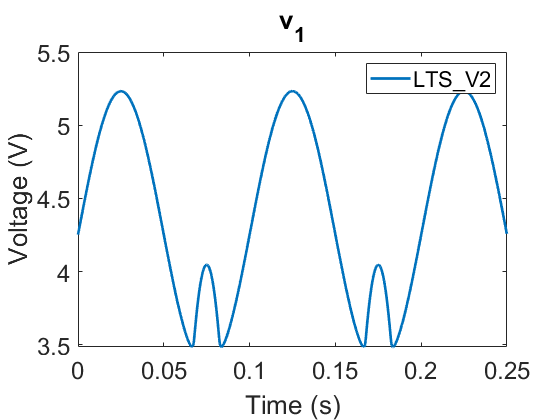

set(gca,'Fontsize',18);
hold off;